# **RS-MILP-09-03: IAC Main Algorithm**

**UT Austin CDUS**

**Hongseok Kim**

## **Mission Sequencing**

- 현재 확보: FRT, L2 NRHO, L4/L5 vertical orbit trajectory

- Look-up chart: 전체적인 한바퀴 데이터 산출

- Constellation 구성/최적화 문제 구성

- FRT 위성 대수 / Servicing 위성 대수에 따른 서비스 성능 분석

- Single SAT - 교신현황 (by 1 loop)

## I. FRT, L2 NRHO, L4/L5 Vertical Orbit Trajctory 생성 $\Delta t$ 에 따른 위치 집합 생성 -> 간격 고려

### I.1 궤적 Point 생성

clear; clc;

addpath('~/Desktop/Redstone_MILP/RS_MILP_09_IAC/RS_MILP_09_03_IAC_Main_Algorithm/')
m1 = 398600.4418; 
m2 = 4902.800076; 

global mu 

mu = m2 / (m1 + m2);

number_of_timesteps = 2000;

% Free Return Trajectory
rv0_FRT = [-0.024087817019224;
           -0.013199742313013;
            0;
            7.725332506766247;
           -7.042775379786875;
            0];

tf_FRT = 1.304372141714530;
t_FRT_vector = (0:tf_FRT/number_of_timesteps:tf_FRT)'

t_FRT_vector =             0
   0.00065219
    0.0013044
    0.0019566
    0.0026087
    0.0032609
    0.0039131
    0.0045653
    0.0052175
    0.0058697
    0.0065219
     0.007174
    0.0078262
    0.0084784
    0.0091306



odeopt = odeset('RelTol',1e-10,'AbsTol',1e-10);
[t_FRT, rv_FRT] = ode45(@CRTBP, t_FRT_vector, rv0_FRT, odeopt);
r_final = rv_FRT(end,1:2).';


%% NRHO-South #742

rv0_NRHO_south = [1.0118016478467127E+0
                  2.7862723172731632E-27
                  -1.7388786181524768E-1	
                  -6.5977076420792335E-13	
                  -7.9865444979787661E-2	
                  -9.5808807140677979E-12];

NRHO_south_period = 1.3739476422245205E+0;
t_NRHO_vector = 0:NRHO_south_period/number_of_timesteps:NRHO_south_period;


[t_NRHO_south, rv_NRHO_south] = ode45(@CRTBP, t_NRHO_vector, rv0_NRHO_south, odeopt);


% L4 / L5 Vertical Orbits

%% L4 Vertical #1020

rv0_L4_vertical = [6.3891964038363835E-1	
                   4.2544999999999999E-1	
                   6.3338764777407142E-1	
                   -3.1073088790628428E-1	
                   -4.8651604983496066E-1	
                   6.4806934253088289E-1];

L4_period = 6.2976761954249154E+0;
t_L4_vector = 0:L4_period/number_of_timesteps:L4_period;
[t_L4, rv_L4] = ode45(@CRTBP, t_L4_vector,rv0_L4_vertical, odeopt);



%% L5 Vertical #1020

rv0_L5_vertical = [6.3891964038363835E-1	
                   -4.2544999999999999E-1	
                   6.3338764777407142E-1	
                   3.1073088790628428E-1	
                   -4.8651604983496066E-1	
                   -6.4806934253088289E-1];

L5_period = 6.2976761954249154E+0;


[t_L5, rv_L5] = ode45(@CRTBP, t_L4_vector,rv0_L5_vertical, odeopt);



number_of_FRT_SATs = 10;
number_of_NRHO_SATs = 20;
number_of_L4_SATs = 20;
number_of_L5_SATs = 20;

rv0_FRT_SATs = rv_FRT(1:number_of_timesteps/number_of_FRT_SATs:(number_of_timesteps -number_of_timesteps/number_of_FRT_SATs+1) ,1:6)

rv0_FRT_SATs =     -0.024088      -0.0132            0       7.7253      -7.0428            0
      0.34885       0.1203            0       1.7649      0.70282            0
      0.55156       0.1724            0       1.4003      0.13987            0
      0.72038      0.16374            0       1.1972     -0.25546            0
      0.86509      0.10889            0       1.0253     -0.57911            0
      0.99233  -0.00046117            0     -0.10748      -2.5651            0
      0.86491      -0.1093            0      -1.0247     -0.57993            0
      0.72024     -0.16427            0       -1.197     -0.25636            0
      0.55144     -0.17304            0      -1.4003      0.13911            0
      0.34875     -0.12101            0      -1.7645      0.70264            0


rv0_NRHO_south_SATs  = rv_NRHO_south(1:number_of_timesteps/number_of_NRHO_SATs:(number_of_timesteps -number_of_timesteps/number_of_NRHO_SATs+1) ,1:6)

rv0_NRHO_south_SATs =        1.0118   2.7863e-27     -0.17389  -6.5977e-13    -0.079865  -9.5809e-12
       1.0116    -0.005466      -0.1726   -0.0071836    -0.078967     0.037471
       1.0108    -0.010808     -0.16873    -0.014361    -0.076225      0.07556
       1.0096    -0.015893     -0.16219    -0.021524    -0.071485      0.11499
       1.0079    -0.020577     -0.15287    -0.028655    -0.064439      0.15675
       1.0056    -0.024681     -0.14057    -0.035723    -0.054509      0.20234
        1.003    -0.027975     -0.12493    -0.042677    -0.040553      0.25435
      0.99979    -0.030105     -0.10536     -0.04944    -0.020035      0.31795
      0.99617    -0.030426    -0.080706    -0.055914     0.014143      0.40572
      0.99211    -0.027221     -0.04814     -0.06226     0.093751      0.56282
      0.98762  -7.9845e-08    0.0047531  -9.8651e-07       2.2361    1.916e-05
      0.99211     0.027221     -0.04814      0.06226     0.093751     -0.56282
      0.99617     0.030426    

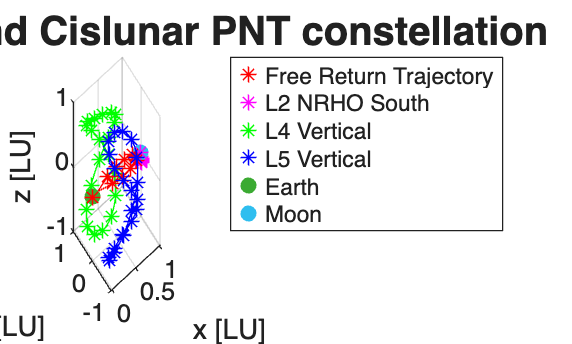

rv0_L4_vertical_SATs = rv_L4(1:number_of_timesteps/number_of_L4_SATs:(number_of_timesteps -number_of_timesteps/number_of_L4_SATs+1) ,1:6);
rv0_L5_vertical_SATs = rv_L5(1:number_of_timesteps/number_of_L5_SATs:(number_of_timesteps -number_of_timesteps/number_of_L5_SATs+1) ,1:6);

figure;
scatter3(rv0_FRT_SATs(:,1),rv0_FRT_SATs(:,2),rv0_FRT_SATs(:,3),"*",'r')
hold on
scatter3(rv0_NRHO_south_SATs(:,1),rv0_NRHO_south_SATs(:,2),rv0_NRHO_south_SATs(:,3),'*','m')
scatter3(rv0_L4_vertical_SATs(:,1),rv0_L4_vertical_SATs(:,2),rv0_L4_vertical_SATs(:,3),'*','g')
scatter3(rv0_L5_vertical_SATs(:,1),rv0_L5_vertical_SATs(:,2),rv0_L5_vertical_SATs(:,3),'*','b')
scatter3(-mu,0,0,'o','filled')
scatter3(1-mu,0,0,'o','filled')

plot3(rv_FRT(:,1),rv_FRT(:,2), rv_FRT(:,3),'r')
plot3(rv_NRHO_south(:,1),rv_NRHO_south(:,2), rv_NRHO_south(:,3),'m')
plot3(rv_L4(:,1),rv_L4(:,2),rv_L4(:,3),'g')
plot3(rv_L5(:,1),rv_L5(:,2),rv_L5(:,3),'b')
hold off

title('FRT satellites and Cislunar PNT constellation','FontSize',15,'FontWeight','bold')
xlabel('x [LU]')
ylabel('y [LU]')
zlabel('z [LU]')
legend('Free Return Trajectory', 'L2 NRHO South', 'L4 Vertical', 'L5 Vertical','Earth','Moon')

## II. Look-up chart: 전체적인 한바퀴 데이터 산출

number_of_timesteps = 100;

t_vector =  (0:tf_FRT/number_of_timesteps:tf_FRT)';

[t, rv_FRT_one] = ode45(@CRTBP, t_vector, rv0_FRT, odeopt);

rv_NRHO_constellation = zeros(length(t_vector),6,number_of_NRHO_SATs);
rv_L4_constellation =  zeros(length(t_vector),6,number_of_L4_SATs);
rv_L5_constellation = zeros(length(t_vector),6,number_of_L5_SATs);

for NRHO_index = 1:number_of_NRHO_SATs
  rv0_NRHO_i = rv0_NRHO_south_SATs(NRHO_index,:)';
  [t, rv_NRHO_i] = ode45(@CRTBP, t_vector, rv0_NRHO_i, odeopt);  
  rv_NRHO_constellation(:,:,NRHO_index) = rv_NRHO_i;
end


for L4_index = 1:number_of_L4_SATs
  rv0_L4_i = rv0_L4_vertical_SATs(L4_index,:)';
  [t, rv_L4_i] = ode45(@CRTBP, t_vector, rv0_L4_i, odeopt);  
  rv_L4_constellation(:,:,L4_index) = rv_L4_i;
end


for L5_index = 1:number_of_L5_SATs
  rv0_L5_i = rv0_L5_vertical_SATs(L5_index,:)';
  [t, rv_L5_i] = ode45(@CRTBP, t_vector, rv0_L5_i, odeopt);  
  rv_L5_constellation(:,:,L5_index) = rv_L5_i;
end

%% Calculate GDOP
%
% Navigation sources:
%   1) Earth
%   2) One NRHO satellite
%   3) One L4 satellite
%   4) One L5 satellite
%
% For each timestep:
% number of combinations =
% number_of_NRHO_SATs * number_of_L4_SATs * number_of_L5_SATs

nTime = length(t_vector);

nCombination = ...
    number_of_NRHO_SATs * ...
    number_of_L4_SATs * ...
    number_of_L5_SATs;

%% ------------------------------------------------------------------------
% Preallocation
% -------------------------------------------------------------------------

GDOP_history = NaN(nTime, nCombination);

% Satellite index tracking
NRHO_index_history = zeros(nCombination,1);
L4_index_history   = zeros(nCombination,1);
L5_index_history   = zeros(nCombination,1);

% Combination index
combination_index = 0;

for NRHO_index = 1:number_of_NRHO_SATs
    for L4_index = 1:number_of_L4_SATs
        for L5_index = 1:number_of_L5_SATs

            combination_index = combination_index + 1;

            NRHO_index_history(combination_index) = NRHO_index;
            L4_index_history(combination_index)   = L4_index;
            L5_index_history(combination_index)   = L5_index;

        end
    end
end

%% ------------------------------------------------------------------------
% GDOP calculation
% -------------------------------------------------------------------------

% Earth position
r_Earth = [-mu; 0; 0];

for time_index = 1:nTime

    % -------------------------------------------------------------
    % FRT client satellite position
    % -------------------------------------------------------------
    r_FRT = rv_FRT_one(time_index,1:3)';

    combination_index = 0;

    for NRHO_index = 1:number_of_NRHO_SATs

        r_NRHO = ...
            rv_NRHO_constellation(time_index,1:3,NRHO_index)';

        for L4_index = 1:number_of_L4_SATs

            r_L4 = ...
                rv_L4_constellation(time_index,1:3,L4_index)';

            for L5_index = 1:number_of_L5_SATs

                combination_index = combination_index + 1;

                r_L5 = ...
                    rv_L5_constellation(time_index,1:3,L5_index)';

                %% -------------------------------------------------
                % Line-of-sight vectors
                % -------------------------------------------------

                rho_Earth = r_Earth - r_FRT;
                rho_NRHO  = r_NRHO  - r_FRT;
                rho_L4    = r_L4    - r_FRT;
                rho_L5    = r_L5    - r_FRT;

                %% Unit LOS vectors
                u_Earth = rho_Earth / norm(rho_Earth);
                u_NRHO  = rho_NRHO  / norm(rho_NRHO);
                u_L4    = rho_L4    / norm(rho_L4);
                u_L5    = rho_L5    / norm(rho_L5);

                %% -------------------------------------------------
                % Geometry Matrix
                %
                % Position + clock bias estimation
                % -------------------------------------------------

                H = [
                    u_Earth'  1
                    u_NRHO'   1
                    u_L4'     1
                    u_L5'     1
                ];

                %% -------------------------------------------------
                % GDOP
                % -------------------------------------------------

                HTH = H' * H;

                % Numerical singularity check
                if rcond(HTH) > 1e-12

                    Q = inv(HTH);

                    GDOP = sqrt(trace(Q));

                else

                    % Bad / singular geometry
                    GDOP = Inf;

                end

                GDOP_history(time_index, combination_index) = GDOP;

            end
        end
    end
end

%% Combination information table

combination_table = table( ...
    (1:nCombination)', ...
    NRHO_index_history, ...
    L4_index_history, ...
    L5_index_history, ...
    'VariableNames', { ...
        'CombinationIndex', ...
        'NRHO_Index', ...
        'L4_Index', ...
        'L5_Index'})

combination_table = 8000×4 table
    CombinationIndex    NRHO_Index    L4_Index    L5_Index
    ________________    __________    ________    ________

            1               1            1            1   
            2               1            1            2   
            3               1            1            3   
            4               1            1            4   
            5               1            1            5   
            6               1            1            6   
            7               1            1            7   
            8               1            1            8   
            9               1            1            9   
           10               1            1           10   
           11               1            1           11   
           12               1            1           12   
           13               1            1           13   
           14               1            1           14   
           15         

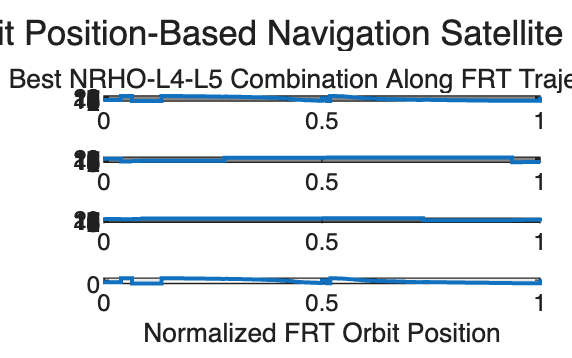


%% ========================================================================
%  FRT Position-Based Best Combination Lookup Chart
% ========================================================================

% Best combination at each timestep
[min_GDOP, best_combination_index] = min(GDOP_history, [], 2);

best_NRHO_index = NRHO_index_history(best_combination_index);
best_L4_index   = L4_index_history(best_combination_index);
best_L5_index   = L5_index_history(best_combination_index);

%% ------------------------------------------------------------------------
% FRT trajectory information
% -------------------------------------------------------------------------

r_FRT_history = rv_FRT_one(:,1:3);

% Distance traveled along the FRT trajectory
FRT_path_distance = zeros(length(t_vector),1);

for time_index = 2:length(t_vector)

    dr = ...
        r_FRT_history(time_index,:) - ...
        r_FRT_history(time_index-1,:);

    FRT_path_distance(time_index) = ...
        FRT_path_distance(time_index-1) + norm(dr);

end

% Normalized orbit position
% 0 = initial FRT position
% 1 = final FRT position
FRT_orbit_position = ...
    FRT_path_distance ./ FRT_path_distance(end);


%% ========================================================================
% Figure 1
% Best NRHO-L4-L5 Combination Lookup Chart
% ========================================================================

figure( ...
    'Name','Best Navigation Satellite Combination Lookup Chart', ...
    'Position',[100 100 1200 750]);

tiledlayout(4,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');


%% ------------------------------------------------------------------------
% 1. Best NRHO satellite index
% -------------------------------------------------------------------------

nexttile;

stairs( ...
    FRT_orbit_position, ...
    best_NRHO_index, ...
    'LineWidth',1.5);

ylabel('NRHO Index');

title('Best NRHO-L4-L5 Combination Along FRT Trajectory');

grid on;
box on;

ylim([0.5 number_of_NRHO_SATs + 0.5]);
yticks(1:number_of_NRHO_SATs);


%% ------------------------------------------------------------------------
% 2. Best L4 satellite index
% -------------------------------------------------------------------------

nexttile;

stairs( ...
    FRT_orbit_position, ...
    best_L4_index, ...
    'LineWidth',1.5);

ylabel('L4 Index');

grid on;
box on;

ylim([0.5 number_of_L4_SATs + 0.5]);
yticks(1:number_of_L4_SATs);


%% ------------------------------------------------------------------------
% 3. Best L5 satellite index
% -------------------------------------------------------------------------

nexttile;

stairs( ...
    FRT_orbit_position, ...
    best_L5_index, ...
    'LineWidth',1.5);

ylabel('L5 Index');

grid on;
box on;

ylim([0.5 number_of_L5_SATs + 0.5]);
yticks(1:number_of_L5_SATs);


%% ------------------------------------------------------------------------
% 4. Best combination index
% -------------------------------------------------------------------------

nexttile;

stairs( ...
    FRT_orbit_position, ...
    best_combination_index, ...
    'LineWidth',1.5);

xlabel('Normalized FRT Orbit Position');
ylabel('Combination Index');

grid on;
box on;

xlim([0 1]);

sgtitle( ...
    'FRT Orbit Position-Based Navigation Satellite Lookup Chart');

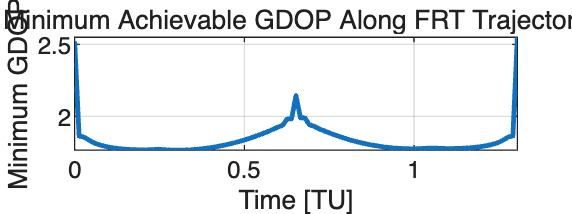



%% ========================================================================
% Figure 2
% Minimum GDOP vs Time
% ========================================================================

figure( ...
    'Name','Minimum GDOP History', ...
    'Position',[100 100 1200 450]);

plot( ...
    t_vector, ...
    min_GDOP, ...
    'LineWidth',1.8);

xlabel('Time [TU]');
ylabel('Minimum GDOP');

title('Minimum Achievable GDOP Along FRT Trajectory');

grid on;
box on;

xlim([t_vector(1) t_vector(end)]);

## III. Constellation 구성/최적화 문제 구성 -> Absolute GDOP / Gradient Approach / Epigraph Approach (모든 조합을 찾는것은 불가능하다!, 대응방안 필요)

%% ========================================================================
% Dynamic FRT Satellite Generation / Removal
%
% Concept:
%
%   - N FRT satellites are always maintained.
%   - Initial satellites are equally phase-spaced along one FRT period.
%   - Every phase_dt = tf_FRT / N:
%         1) Remove the leading satellite
%         2) Generate a new satellite at the t = 0 position
%
%   - Each satellite has a unique physical ID.
%
% Output:
%
%   rv_FRT_dynamic         : [nTime x 6 x N]
%   FRT_ID_history         : [nTime x N]
%   FRT_age_history        : [nTime x N]
%   FRT_generation_history : event table
% ========================================================================


%% ------------------------------------------------------------------------
% Basic parameters
% -------------------------------------------------------------------------

N_FRT = number_of_FRT_SATs;

T_FRT = tf_FRT;

phase_dt = T_FRT / N_FRT;

nTime = length(t_vector);


%% ------------------------------------------------------------------------
% Reference FRT orbit
% -------------------------------------------------------------------------
%
% rv_FRT should contain one complete FRT orbit.
%
% Ideally:
%
% size(rv_FRT,1) == length(t_vector)
%
% so that
%
% rv_FRT(k,:) = FRT state at t_vector(k)
%

if size(rv_FRT,1) == length(t_vector)

    t_FRT_reference = t_vector;

else

    % Fallback if a separate reference time vector was not saved
    t_FRT_reference = linspace( ...
        0, ...
        T_FRT, ...
        size(rv_FRT,1))';

end


%% ========================================================================
% Initial FRT constellation
% ========================================================================

initial_phase = ...
    (0:N_FRT-1)' * phase_dt;

rv0_FRT_SATs = zeros(N_FRT,6);

for sat_index = 1:N_FRT

    rv0_FRT_SATs(sat_index,:) = interp1( ...
        t_FRT_reference, ...
        rv_FRT(:,1:6), ...
        initial_phase(sat_index), ...
        'pchip');

end


%% ========================================================================
% Preallocate dynamic constellation history
% ========================================================================

rv_FRT_dynamic = NaN( ...
    nTime, ...
    6, ...
    N_FRT);

% Physical satellite ID occupying each orbital phase slot
FRT_ID_history = NaN( ...
    nTime, ...
    N_FRT);

% Age of each satellite since entering t = 0 position
FRT_age_history = NaN( ...
    nTime, ...
    N_FRT);

% Phase slot:
%
% slot 1 -> closest to t = 0 position
% slot 2 -> phase_dt ahead
% ...
% slot N -> (N-1)*phase_dt ahead


%% ========================================================================
% Dynamic constellation propagation
% ========================================================================

numerical_tol = ...
    1e-10 * max(1,T_FRT);

for time_index = 1:nTime

    current_time = t_vector(time_index);


    %% --------------------------------------------------------------------
    % Number of generation/removal events that have occurred
    %
    % event_count = 0:
    %     initial constellation
    %
    % event_count = 1:
    %     one satellite removed
    %     one new satellite generated
    %
    % etc.
    % ---------------------------------------------------------------------

    event_count = floor( ...
        (current_time + numerical_tol) / phase_dt);

    event_count = min( ...
        event_count, ...
        N_FRT);


    %% --------------------------------------------------------------------
    % Time elapsed since the latest insertion event
    % ---------------------------------------------------------------------

    time_since_event = ...
        current_time - event_count * phase_dt;

    if abs(time_since_event) < numerical_tol
        time_since_event = 0;
    end


    %% --------------------------------------------------------------------
    % Current phase of all N satellites
    %
    % Regardless of physical ID, active satellites occupy
    %
    %   tau
    %   tau + phase_dt
    %   ...
    %   tau + (N-1) phase_dt
    %
    % ---------------------------------------------------------------------

    satellite_age = ...
        time_since_event + ...
        (0:N_FRT-1)' * phase_dt;


    %% --------------------------------------------------------------------
    % Determine physical satellite IDs
    % ---------------------------------------------------------------------
    %
    % At t = 0:
    %
    % phase slot:
    %     0      dt      2dt ... (N-1)dt
    %
    % ID:
    %     1       2       3  ... N
    %
    %
    % After first event:
    %
    %     N+1     1       2  ... N-1
    %
    %
    % After second event:
    %
    %     N+2    N+1      1  ... N-2
    %
    % ---------------------------------------------------------------------

    current_IDs = zeros(N_FRT,1);

    m = event_count;

    if m == 0

        current_IDs = (1:N_FRT)';

    else

        %% Newly inserted satellites

        for slot_index = 1:m

            current_IDs(slot_index) = ...
                N_FRT + m - slot_index + 1;

        end


        %% Surviving initial satellites

        if m < N_FRT

            current_IDs(m+1:end) = ...
                (1:N_FRT-m)';

        end

    end


    %% --------------------------------------------------------------------
    % Obtain state from periodic FRT reference trajectory
    % ---------------------------------------------------------------------

    for slot_index = 1:N_FRT

        phase_time = ...
            satellite_age(slot_index);

        rv_current = interp1( ...
            t_FRT_reference, ...
            rv_FRT(:,1:6), ...
            phase_time, ...
            'pchip');

        rv_FRT_dynamic( ...
            time_index,:,slot_index) = ...
            rv_current;

    end


    %% Store ID and phase information

    FRT_ID_history(time_index,:) = ...
        current_IDs';

    FRT_age_history(time_index,:) = ...
        satellite_age';

end

%% ========================================================================
% Generation / Removal Event History
% ========================================================================

number_of_events = N_FRT;

EventNumber = (1:number_of_events)';

EventTime = ...
    EventNumber * phase_dt;

RemovedSatelliteID = zeros( ...
    number_of_events,1);

CreatedSatelliteID = zeros( ...
    number_of_events,1);


for event_index = 1:number_of_events

    %% -------------------------------------------------------------
    % Removed satellite
    %
    % Removal sequence:
    %
    % 10, 9, 8, ..., 1
    %
    % --------------------------------------------------------------

    RemovedSatelliteID(event_index) = ...
        N_FRT - event_index + 1;


    %% -------------------------------------------------------------
    % Newly created satellite
    %
    % New IDs:
    %
    % 11, 12, 13, ...
    %
    % --------------------------------------------------------------

    CreatedSatelliteID(event_index) = ...
        N_FRT + event_index;

end


FRT_generation_history = table( ...
    EventNumber, ...
    EventTime, ...
    RemovedSatelliteID, ...s
    CreatedSatelliteID);


disp(FRT_generation_history);

    EventNumber    EventTime    RemovedSatelliteID    CreatedSatelliteID
    ___________    _________    __________________    __________________

         1          0.13044             10                    11        
         2          0.26087              9                    12        
         3          0.39131              8                    13        
         4          0.52175              7                    14        
         5          0.65219              6                    15        
         6          0.78262              5                    16        
         7          0.91306              4                    17        
         8           1.0435              3                    18        
         9           1.1739              2                    19        
        10           1.3044              1                    20        



%% ========================================================================
% ID-AWARE OPTIMAL GDOP LOOKUP FOR ALL ACTIVE FRT SATELLITES
%
% For every timestep and every active FRT satellite:
%
%   FRT_i -> Earth + NRHO_j + L4_k + L5_l
%
% Find:
%
%   minimum GDOP
%   best NRHO ID
%   best L4 ID
%   best L5 ID
%   best combination index
%
% Also retain Top-K candidates for later task allocation.
% ========================================================================


%% ------------------------------------------------------------------------
% Parameters
% -------------------------------------------------------------------------

nTime = length(t_vector);

N_FRT  = number_of_FRT_SATs;
N_NRHO = number_of_NRHO_SATs;
N_L4   = number_of_L4_SATs;
N_L5   = number_of_L5_SATs;

nCombination = ...
    N_NRHO * N_L4 * N_L5;

% Number of candidate combinations retained for each FRT satellite
TOP_K = 60;

% Numerical singularity tolerance
GDOP_rcond_tolerance = 1e-12;


%% ------------------------------------------------------------------------
% Earth position
% -------------------------------------------------------------------------
%
% IMPORTANT:
%
% If your CRTBP frame is Earth-centered:
%       r_Earth = [0;0;0]
%
% If it is the standard barycentric CR3BP rotating frame:
%       r_Earth = [-mu;0;0]
%

r_Earth = [-mu; 0; 0];


%% ========================================================================
% Combination index mapping
%
% CombinationIndex -> NRHO / L4 / L5
% ========================================================================

comb_NRHO = zeros(nCombination,1);
comb_L4   = zeros(nCombination,1);
comb_L5   = zeros(nCombination,1);

combination_index = 0;

for NRHO_index = 1:N_NRHO
    for L4_index = 1:N_L4
        for L5_index = 1:N_L5

            combination_index = combination_index + 1;

            comb_NRHO(combination_index) = NRHO_index;
            comb_L4(combination_index)   = L4_index;
            comb_L5(combination_index)   = L5_index;

        end
    end
end


combination_table = table( ...
    (1:nCombination)', ...
    comb_NRHO, ...
    comb_L4, ...
    comb_L5, ...
    'VariableNames',{ ...
        'CombinationIndex', ...
        'NRHO_ID', ...
        'L4_ID', ...
        'L5_ID'});


%% ========================================================================
% Preallocate BEST solution history
% ========================================================================

best_GDOP_history = NaN(nTime,N_FRT);

best_combination_index_history = NaN(nTime,N_FRT);

best_NRHO_ID_history = NaN(nTime,N_FRT);
best_L4_ID_history   = NaN(nTime,N_FRT);
best_L5_ID_history   = NaN(nTime,N_FRT);


%% ========================================================================
% Preallocate Top-K history
%
% dimensions:
%
%   time x FRT slot x candidate rank
% ========================================================================

topK_GDOP_history = NaN( ...
    nTime, ...
    N_FRT, ...
    TOP_K);

topK_combination_index_history = NaN( ...
    nTime, ...
    N_FRT, ...
    TOP_K);

topK_NRHO_ID_history = NaN( ...
    nTime, ...
    N_FRT, ...
    TOP_K);

topK_L4_ID_history = NaN( ...
    nTime, ...
    N_FRT, ...
    TOP_K);

topK_L5_ID_history = NaN( ...
    nTime, ...
    N_FRT, ...
    TOP_K);


%% ========================================================================
% MAIN GDOP LOOP
% ========================================================================

I4 = eye(4);

for time_index = 1:nTime

    fprintf( ...
        'GDOP calculation: timestep %d / %d\n', ...
        time_index, ...
        nTime);


    %% --------------------------------------------------------------------
    % Servicing satellite positions at current timestep
    % ---------------------------------------------------------------------

    r_NRHO_all = squeeze( ...
        rv_NRHO_constellation(time_index,1:3,:))';

    r_L4_all = squeeze( ...
        rv_L4_constellation(time_index,1:3,:))';

    r_L5_all = squeeze( ...
        rv_L5_constellation(time_index,1:3,:))';


    %% ====================================================================
    % Loop through all currently active FRT satellites
    % ====================================================================

    for FRT_slot = 1:N_FRT

        %% ================================================================
        % Current FRT satellite
        % ================================================================
        
        current_FRT_ID = ...
            FRT_ID_history(time_index,FRT_slot);
        
        
        %% -------------------------------------------------------------
        % Current FRT position
        %
        % IMPORTANT:
        % Always force it to 1 x 3 row vector
        % -------------------------------------------------------------
        
        r_FRT = reshape( ...
            rv_FRT_dynamic(time_index,1:3,FRT_slot), ...
            1,3);
        
        
        %% ================================================================
        % Earth LOS
        % ================================================================
        
        % Earth = 3 x 1 column
        % r_FRT' = 3 x 1 column
        
        rho_Earth = ...
            r_Earth - r_FRT';
        
        d_Earth = ...
            norm(rho_Earth);
        
        if d_Earth <= eps
            continue;
        end
        
        u_Earth = ...
            rho_Earth / d_Earth;
        
        % Force 3 x 1
        u_Earth = ...
            u_Earth(:);
        
        % 4 x 1
        h_Earth = [
            u_Earth
            1
            ];
        
        % 4 x 4
        M_Earth = ...
            h_Earth * h_Earth';
        
        
        %% ================================================================
        % NRHO LOS
        % ================================================================
        %
        % r_NRHO_all : N_NRHO x 3
        % r_FRT      : 1 x 3
        %
        % MATLAB implicit expansion:
        %
        % [N_NRHO x 3] - [1 x 3]
        %
        % => [N_NRHO x 3]
        %
        
        rho_NRHO = ...
            r_NRHO_all - r_FRT;
        
        d_NRHO = ...
            vecnorm( ...
                rho_NRHO, ...
                2, ...
                2);
        
        u_NRHO = ...
            rho_NRHO ./ d_NRHO;
        
        H_NRHO = [
            u_NRHO, ...
            ones(N_NRHO,1)
            ];
        
        
        %% ================================================================
        % L4 LOS
        % ================================================================
        
        rho_L4 = ...
            r_L4_all - r_FRT;
        
        d_L4 = ...
            vecnorm( ...
                rho_L4, ...
                2, ...
                2);
        
        u_L4 = ...
            rho_L4 ./ d_L4;
        
        H_L4 = [
            u_L4, ...
            ones(N_L4,1)
            ];
        
        
        %% ================================================================
        % L5 LOS
        % ================================================================
        
        rho_L5 = ...
            r_L5_all - r_FRT;
        
        d_L5 = ...
            vecnorm( ...
                rho_L5, ...
                2, ...
                2);
        
        u_L5 = ...
            rho_L5 ./ d_L5;
        
        H_L5 = [
            u_L5, ...
            ones(N_L5,1)
            ];

        %% ================================================================
        % Precompute individual H'H contributions
        % ================================================================

        M_NRHO = zeros(4,4,N_NRHO);
        M_L4   = zeros(4,4,N_L4);
        M_L5   = zeros(4,4,N_L5);


        for i = 1:N_NRHO

            h = H_NRHO(i,:)';

            M_NRHO(:,:,i) = ...
                h * h';

        end


        for i = 1:N_L4

            h = H_L4(i,:)';

            M_L4(:,:,i) = ...
                h * h';

        end


        for i = 1:N_L5

            h = H_L5(i,:)';

            M_L5(:,:,i) = ...
                h * h';

        end


        %% ================================================================
        % Evaluate all candidate combinations
        % ================================================================

        GDOP_candidates = ...
            Inf(nCombination,1);

        combination_index = 0;


        for NRHO_index = 1:N_NRHO

            M_EN = ...
                M_Earth + ...
                M_NRHO(:,:,NRHO_index);


            for L4_index = 1:N_L4

                M_EN4 = ...
                    M_EN + ...
                    M_L4(:,:,L4_index);


                for L5_index = 1:N_L5

                    combination_index = ...
                        combination_index + 1;


                    HTH = ...
                        M_EN4 + ...
                        M_L5(:,:,L5_index);


                    %% -------------------------------------------------
                    % Check geometry singularity
                    % -------------------------------------------------

                    if rcond(HTH) > GDOP_rcond_tolerance

                        Q = ...
                            HTH \ I4;

                        current_GDOP = ...
                            sqrt(trace(Q));

                    else

                        current_GDOP = Inf;

                    end


                    GDOP_candidates( ...
                        combination_index) = ...
                        current_GDOP;

                end
            end
        end


        %% ================================================================
        % Find Top-K candidates
        % ================================================================

        [sorted_GDOP, sorted_index] = ...
            mink(GDOP_candidates,TOP_K);


        %% -------------------------------------------------------------
        % Best solution
        % -------------------------------------------------------------

        best_index = ...
            sorted_index(1);

        best_GDOP_history( ...
            time_index,FRT_slot) = ...
            sorted_GDOP(1);

        best_combination_index_history( ...
            time_index,FRT_slot) = ...
            best_index;

        best_NRHO_ID_history( ...
            time_index,FRT_slot) = ...
            comb_NRHO(best_index);

        best_L4_ID_history( ...
            time_index,FRT_slot) = ...
            comb_L4(best_index);

        best_L5_ID_history( ...
            time_index,FRT_slot) = ...
            comb_L5(best_index);


        %% -------------------------------------------------------------
        % Top-K solutions
        % -------------------------------------------------------------

        for rank_index = 1:TOP_K

            candidate_index = ...
                sorted_index(rank_index);

            topK_GDOP_history( ...
                time_index, ...
                FRT_slot, ...
                rank_index) = ...
                sorted_GDOP(rank_index);

            topK_combination_index_history( ...
                time_index, ...
                FRT_slot, ...
                rank_index) = ...
                candidate_index;

            topK_NRHO_ID_history( ...
                time_index, ...
                FRT_slot, ...
                rank_index) = ...
                comb_NRHO(candidate_index);

            topK_L4_ID_history( ...
                time_index, ...
                FRT_slot, ...
                rank_index) = ...
                comb_L4(candidate_index);

            topK_L5_ID_history( ...
                time_index, ...
                FRT_slot, ...
                rank_index) = ...
                comb_L5(candidate_index);

        end

    end
end

GDOP calculation: timestep 1 / 101
GDOP calculation: timestep 2 / 101
GDOP calculation: timestep 3 / 101
GDOP calculation: timestep 4 / 101
GDOP calculation: timestep 5 / 101
GDOP calculation: timestep 6 / 101
GDOP calculation: timestep 7 / 101
GDOP calculation: timestep 8 / 101
GDOP calculation: timestep 9 / 101
GDOP calculation: timestep 10 / 101
GDOP calculation: timestep 11 / 101
GDOP calculation: timestep 12 / 101
GDOP calculation: timestep 13 / 101
GDOP calculation: timestep 14 / 101
GDOP calculation: timestep 15 / 101
GDOP calculation: timestep 16 / 101
GDOP calculation: timestep 17 / 101
GDOP calculation: timestep 18 / 101
GDOP calculation: timestep 19 / 101
GDOP calculation: timestep 20 / 101
GDOP calculation: timestep 21 / 101
GDOP calculation: timestep 22 / 101
GDOP calculation: timestep 23 / 101
GDOP calculation: timestep 24 / 101
GDOP calculation: timestep 25 / 101
GDOP calculation: timestep 26 / 101
GDOP calculation: timestep 27 / 101
GDOP calculation: timestep 28 / 101
G


%% ========================================================================
% Construct ID-aware FRT GDOP Lookup Table
% ========================================================================

nRows = ...
    nTime * N_FRT;


%% ------------------------------------------------------------------------
% Time / slot / ID information
% -------------------------------------------------------------------------

TimeIndex = ...
    repmat((1:nTime)',N_FRT,1);

Time = ...
    repmat(t_vector,N_FRT,1);

FRTSlot = ...
    repelem((1:N_FRT)',nTime);

FRT_ID = ...
    reshape( ...
        FRT_ID_history, ...
        [],1);


%% ------------------------------------------------------------------------
% FRT orbital phase
% -------------------------------------------------------------------------

PhaseAge = ...
    reshape( ...
        FRT_age_history, ...
        [],1);

NormalizedPhase = ...
    PhaseAge / T_FRT;


%% ------------------------------------------------------------------------
% FRT position
% -------------------------------------------------------------------------

X_matrix = ...
    squeeze(rv_FRT_dynamic(:,1,:));

Y_matrix = ...
    squeeze(rv_FRT_dynamic(:,2,:));

Z_matrix = ...
    squeeze(rv_FRT_dynamic(:,3,:));

X = reshape(X_matrix,[],1);
Y = reshape(Y_matrix,[],1);
Z = reshape(Z_matrix,[],1);


%% ------------------------------------------------------------------------
% Optimal GDOP information
% -------------------------------------------------------------------------

BestGDOP = ...
    reshape( ...
        best_GDOP_history, ...
        [],1);

CombinationIndex = ...
    reshape( ...
        best_combination_index_history, ...
        [],1);

BestNRHO_ID = ...
    reshape( ...
        best_NRHO_ID_history, ...
        [],1);

BestL4_ID = ...
    reshape( ...
        best_L4_ID_history, ...
        [],1);

BestL5_ID = ...
    reshape( ...
        best_L5_ID_history, ...
        [],1);


%% ========================================================================
% Final table
% ========================================================================

FRT_GDOP_lookup_table = table( ...
    TimeIndex, ...
    Time, ...
    FRTSlot, ...
    FRT_ID, ...
    PhaseAge, ...
    NormalizedPhase, ...
    X,Y,Z, ...
    BestGDOP, ...
    CombinationIndex, ...
    BestNRHO_ID, ...
    BestL4_ID, ...
    BestL5_ID);


disp(FRT_GDOP_lookup_table(1:20,:));

    TimeIndex      Time      FRTSlot    FRT_ID    PhaseAge    NormalizedPhase        X            Y        Z    BestGDOP    CombinationIndex    BestNRHO_ID    BestL4_ID    BestL5_ID
    _________    ________    _______    ______    ________    _______________    _________    _________    _    ________    ________________    ___________    _________    _________

        1               0       1          1             0            0          -0.024088      -0.0132    0     2.5197           1877               5            14           17    
        2        0.013044       1          1      0.013044         0.01           0.062721    -0.013074    0     1.8631           7675              20             4           15    
        3        0.026087       1          1      0.026087         0.02             0.1138    0.0079415    0     1.8564            117               1             6           17    
        4        0.039131       1          1      0.039131         0.03            0.1539

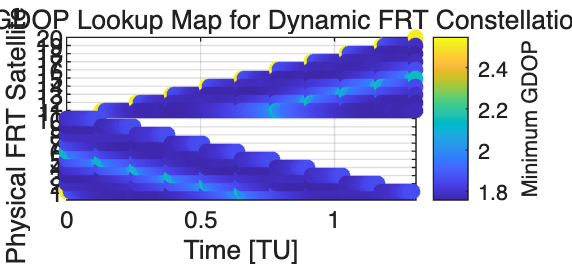

%% ========================================================================
% Figure 1
% Physical FRT ID vs Time - Optimal GDOP Lookup Map
% ========================================================================

validIndex = ...
    isfinite(FRT_GDOP_lookup_table.BestGDOP);


figure( ...
    'Name','FRT ID-Aware GDOP Lookup Map', ...
    'Position',[100 100 1300 600]);

scatter( ...
    FRT_GDOP_lookup_table.Time(validIndex), ...
    FRT_GDOP_lookup_table.FRT_ID(validIndex), ...
    35, ...
    FRT_GDOP_lookup_table.BestGDOP(validIndex), ...
    'filled');

xlabel('Time [TU]');
ylabel('Physical FRT Satellite ID');

title( ...
    'Optimal GDOP Lookup Map for Dynamic FRT Constellation');

cb = colorbar;
cb.Label.String = 'Minimum GDOP';

grid on;
box on;

xlim([t_vector(1) t_vector(end)]);

yticks( ...
    unique(FRT_GDOP_lookup_table.FRT_ID));

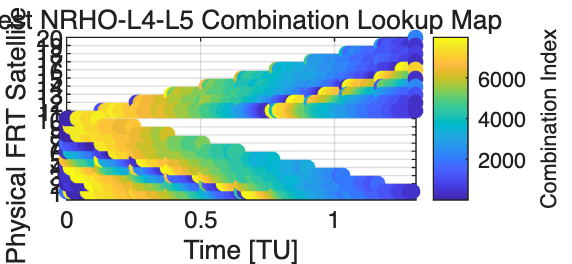

%% ========================================================================
% Figure 2
% Best Combination Index Lookup Map
% ========================================================================

figure( ...
    'Name','Best Combination Lookup Map', ...
    'Position',[100 100 1300 600]);

scatter( ...
    FRT_GDOP_lookup_table.Time, ...
    FRT_GDOP_lookup_table.FRT_ID, ...
    35, ...
    FRT_GDOP_lookup_table.CombinationIndex, ...
    'filled');

xlabel('Time [TU]');
ylabel('Physical FRT Satellite ID');

title( ...
    'Best NRHO-L4-L5 Combination Lookup Map');

cb = colorbar;
cb.Label.String = 'Combination Index';

grid on;
box on;

xlim([t_vector(1) t_vector(end)]);

yticks( ...
    unique(FRT_GDOP_lookup_table.FRT_ID));

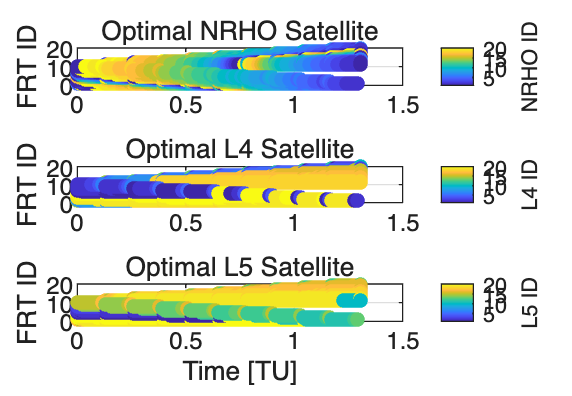

%% ========================================================================
% Figure 3
% Individual Servicing Satellite ID Lookup Maps
% ========================================================================

figure( ...
    'Name','Optimal Servicing Satellite IDs', ...
    'Position',[100 100 1300 900]);

tiledlayout(3,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');


%% ------------------------------------------------------------------------
% NRHO
% -------------------------------------------------------------------------

nexttile;

scatter( ...
    FRT_GDOP_lookup_table.Time, ...
    FRT_GDOP_lookup_table.FRT_ID, ...
    30, ...
    FRT_GDOP_lookup_table.BestNRHO_ID, ...
    'filled');

ylabel('FRT ID');

title('Optimal NRHO Satellite');

cb = colorbar;
cb.Label.String = 'NRHO ID';

grid on;
box on;


%% ------------------------------------------------------------------------
% L4
% -------------------------------------------------------------------------

nexttile;

scatter( ...
    FRT_GDOP_lookup_table.Time, ...
    FRT_GDOP_lookup_table.FRT_ID, ...
    30, ...
    FRT_GDOP_lookup_table.BestL4_ID, ...
    'filled');

ylabel('FRT ID');

title('Optimal L4 Satellite');

cb = colorbar;
cb.Label.String = 'L4 ID';

grid on;
box on;


%% ------------------------------------------------------------------------
% L5
% -------------------------------------------------------------------------

nexttile;

scatter( ...
    FRT_GDOP_lookup_table.Time, ...
    FRT_GDOP_lookup_table.FRT_ID, ...
    30, ...
    FRT_GDOP_lookup_table.BestL5_ID, ...
    'filled');

xlabel('Time [TU]');
ylabel('FRT ID');

title('Optimal L5 Satellite');

cb = colorbar;
cb.Label.String = 'L5 ID';

grid on;
box on;

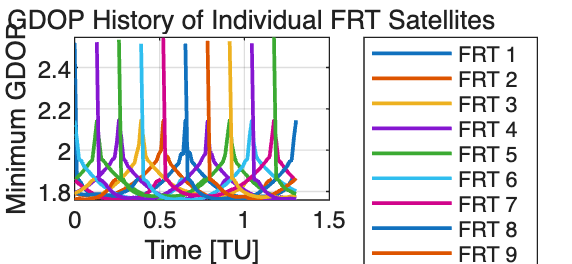

%% ========================================================================
% Figure 4
% GDOP History for Each Physical FRT Satellite
% ========================================================================

unique_FRT_IDs = ...
    unique(FRT_GDOP_lookup_table.FRT_ID);

figure( ...
    'Name','GDOP History by Physical FRT ID', ...
    'Position',[100 100 1300 600]);

hold on;


for ii = 1:length(unique_FRT_IDs)

    current_ID = ...
        unique_FRT_IDs(ii);

    idx = ...
        FRT_GDOP_lookup_table.FRT_ID == current_ID;

    current_time = ...
        FRT_GDOP_lookup_table.Time(idx);

    current_GDOP = ...
        FRT_GDOP_lookup_table.BestGDOP(idx);

    [current_time,sort_index] = ...
        sort(current_time);

    current_GDOP = ...
        current_GDOP(sort_index);


    plot( ...
        current_time, ...
        current_GDOP, ...
        'LineWidth',1.4, ...
        'DisplayName', ...
        sprintf('FRT %d',current_ID));

end


xlabel('Time [TU]');
ylabel('Minimum GDOP');

title( ...
    'Optimal GDOP History of Individual FRT Satellites');

grid on;
box on;

legend( ...
    'Location','eastoutside');

hold off;

- #1만 모은다 (한 위성이 최대 얼마만큼의 위성 서비스를 부담하는가?)

- Conflict Satellite 찾는다

- Centralized Solution: 최적화 문제 한번에 푼다 (scaleability?)

- Distributed Solution: Satellite 사이 task negotiation (순차적 Decision/무작위 Decision)


%% ========================================================================
% TOP-1 SERVICING LOAD ANALYSIS
%
% Question:
% "If every FRT independently selects its minimum-GDOP combination,
%  how many clients request the same servicing satellite?"
% ========================================================================

nTime = length(t_vector);

N_FRT  = number_of_FRT_SATs;
N_NRHO = number_of_NRHO_SATs;
N_L4   = number_of_L4_SATs;
N_L5   = number_of_L5_SATs;


%% ------------------------------------------------------------------------
% Load matrices
%
% row    = timestep
% column = servicing satellite ID
% value  = number of FRT clients requesting that satellite
% -------------------------------------------------------------------------

NRHO_load_history = zeros(nTime,N_NRHO);
L4_load_history   = zeros(nTime,N_L4);
L5_load_history   = zeros(nTime,N_L5);


for time_index = 1:nTime

    %% NRHO
    selected_NRHO = ...
        best_NRHO_ID_history(time_index,:);

    for sat_id = 1:N_NRHO

        NRHO_load_history(time_index,sat_id) = ...
            sum(selected_NRHO == sat_id);

    end


    %% L4
    selected_L4 = ...
        best_L4_ID_history(time_index,:);

    for sat_id = 1:N_L4

        L4_load_history(time_index,sat_id) = ...
            sum(selected_L4 == sat_id);

    end


    %% L5
    selected_L5 = ...
        best_L5_ID_history(time_index,:);

    for sat_id = 1:N_L5

        L5_load_history(time_index,sat_id) = ...
            sum(selected_L5 == sat_id);

    end

end



%% ========================================================================
% Maximum servicing burden
% ========================================================================

[max_NRHO_load, linear_idx] = ...
    max(NRHO_load_history(:));

[max_NRHO_time, max_NRHO_ID] = ...
    ind2sub(size(NRHO_load_history),linear_idx);


[max_L4_load, linear_idx] = ...
    max(L4_load_history(:));

[max_L4_time, max_L4_ID] = ...
    ind2sub(size(L4_load_history),linear_idx);


[max_L5_load, linear_idx] = ...
    max(L5_load_history(:));

[max_L5_time, max_L5_ID] = ...
    ind2sub(size(L5_load_history),linear_idx);


fprintf('\n========================================\n');

fprintf('Maximum Top-1 Servicing Load\n');

Maximum Top-1 Servicing Load


fprintf('========================================\n');


fprintf( ...
    'NRHO %d : %d FRT satellites at timestep %d\n', ...
    max_NRHO_ID, ...
    max_NRHO_load, ...
    max_NRHO_time);

NRHO 1 : 7 FRT satellites at timestep 1



fprintf( ...
    'L4   %d : %d FRT satellites at timestep %d\n', ...
    max_L4_ID, ...
    max_L4_load, ...
    max_L4_time);

L4   1 : 3 FRT satellites at timestep 10



fprintf( ...
    'L5   %d : %d FRT satellites at timestep %d\n', ...
    max_L5_ID, ...
    max_L5_load, ...
    max_L5_time);

L5   1 : 3 FRT satellites at timestep 34


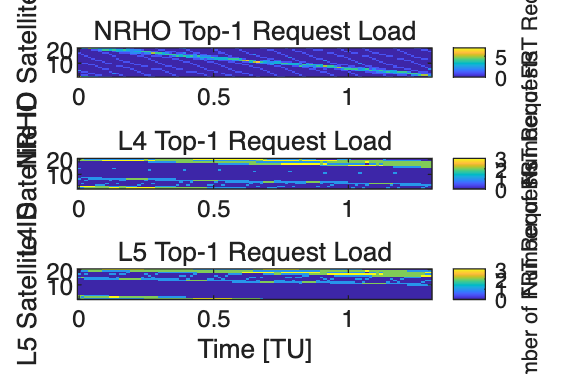


%% ========================================================================
% Top-1 Load Heatmap
% ========================================================================

figure( ...
    'Name','Top-1 Servicing Satellite Load', ...
    'Position',[100 100 1300 850]);

tiledlayout(3,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');


%% NRHO

nexttile;

imagesc( ...
    t_vector, ...
    1:N_NRHO, ...
    NRHO_load_history');

axis xy;

ylabel('NRHO Satellite ID');

title( ...
    'NRHO Top-1 Request Load');

cb = colorbar;
cb.Label.String = 'Number of FRT Requests';


%% L4

nexttile;

imagesc( ...
    t_vector, ...
    1:N_L4, ...
    L4_load_history');

axis xy;

ylabel('L4 Satellite ID');

title( ...
    'L4 Top-1 Request Load');

cb = colorbar;
cb.Label.String = 'Number of FRT Requests';


%% L5

nexttile;

imagesc( ...
    t_vector, ...
    1:N_L5, ...
    L5_load_history');

axis xy;

xlabel('Time [TU]');
ylabel('L5 Satellite ID');

title( ...
    'L5 Top-1 Request Load');

cb = colorbar;
cb.Label.String = 'Number of FRT Requests';

## IV:  Centralized / Sequential Solver

capacity_NRHO = ones(N_NRHO,1)*2;
capacity_L4   = ones(N_L4,1)*2;
capacity_L5   = ones(N_L5,1)*2;

central = solveCentralizedGDOPAssignment( ...
    time_index, ...
    topK_GDOP_history, ...
    topK_NRHO_ID_history, ...
    topK_L4_ID_history, ...
    topK_L5_ID_history, ...
    capacity_NRHO, ...
    capacity_L4, ...
    capacity_L5);

function result = solveCentralizedGDOPAssignment( ...
    time_index, ...
    topK_GDOP_history, ...
    topK_NRHO_ID_history, ...
    topK_L4_ID_history, ...
    topK_L5_ID_history, ...
    capacity_NRHO, ...
    capacity_L4, ...
    capacity_L5)

%% ========================================================================
% Centralized Top-K GDOP Assignment
% ========================================================================

N_FRT = size(topK_GDOP_history,2);
K     = size(topK_GDOP_history,3);

N_NRHO = length(capacity_NRHO);
N_L4   = length(capacity_L4);
N_L5   = length(capacity_L5);


%% ------------------------------------------------------------------------
% Extract timestep
% -------------------------------------------------------------------------

G = reshape( ...
    topK_GDOP_history(time_index,:,:), ...
    N_FRT,K);

NRHO_ID = reshape( ...
    topK_NRHO_ID_history(time_index,:,:), ...
    N_FRT,K);

L4_ID = reshape( ...
    topK_L4_ID_history(time_index,:,:), ...
    N_FRT,K);

L5_ID = reshape( ...
    topK_L5_ID_history(time_index,:,:), ...
    N_FRT,K);


%% ------------------------------------------------------------------------
% Variables
%
% x(i,k)
%
% Linear index:
% (i-1)*K + k
% -------------------------------------------------------------------------

nVar = ...
    N_FRT * K;

f = zeros(nVar,1);

lb = zeros(nVar,1);
ub = ones(nVar,1);


for i = 1:N_FRT

    for k = 1:K

        idx = ...
            (i-1)*K + k;

        if isfinite(G(i,k))

            f(idx) = ...
                G(i,k);

        else

            % Invalid candidate
            f(idx) = 0;
            ub(idx) = 0;

        end

    end
end


%% ========================================================================
% Each FRT selects exactly one candidate
% ========================================================================

Aeq = zeros(N_FRT,nVar);

beq = ones(N_FRT,1);


for i = 1:N_FRT

    idx = ...
        (i-1)*K + (1:K);

    Aeq(i,idx) = 1;

end


%% ========================================================================
% Servicing satellite capacity constraints
% ========================================================================

nConstraint = ...
    N_NRHO + ...
    N_L4 + ...
    N_L5;

A = zeros(nConstraint,nVar);

b = [
    capacity_NRHO(:)
    capacity_L4(:)
    capacity_L5(:)
    ];


row = 0;


%% NRHO capacity

for s = 1:N_NRHO

    row = row + 1;

    for i = 1:N_FRT
        for k = 1:K

            if NRHO_ID(i,k) == s

                idx = ...
                    (i-1)*K + k;

                A(row,idx) = 1;

            end
        end
    end
end


%% L4 capacity

for s = 1:N_L4

    row = row + 1;

    for i = 1:N_FRT
        for k = 1:K

            if L4_ID(i,k) == s

                idx = ...
                    (i-1)*K + k;

                A(row,idx) = 1;

            end
        end
    end
end


%% L5 capacity

for s = 1:N_L5

    row = row + 1;

    for i = 1:N_FRT
        for k = 1:K

            if L5_ID(i,k) == s

                idx = ...
                    (i-1)*K + k;

                A(row,idx) = 1;

            end
        end
    end
end


%% ========================================================================
% Solve MILP
% ========================================================================

intcon = ...
    1:nVar;

options = optimoptions( ...
    'intlinprog', ...
    'Display','off');


[x,fval,exitflag,output] = ...
    intlinprog( ...
        f, ...
        intcon, ...
        A,b, ...
        Aeq,beq, ...
        lb,ub, ...
        options);


%% ========================================================================
% Decode solution
% ========================================================================

result.success = ...
    exitflag > 0;

result.objective = ...
    fval;

result.exitflag = ...
    exitflag;

result.output = ...
    output;


result.rank = NaN(N_FRT,1);
result.GDOP = NaN(N_FRT,1);

result.NRHO_ID = NaN(N_FRT,1);
result.L4_ID   = NaN(N_FRT,1);
result.L5_ID   = NaN(N_FRT,1);


if result.success

    for i = 1:N_FRT

        idx = ...
            (i-1)*K + (1:K);

        selected = ...
            find(x(idx) > 0.5,1);

        result.rank(i) = ...
            selected;

        result.GDOP(i) = ...
            G(i,selected);

        result.NRHO_ID(i) = ...
            NRHO_ID(i,selected);

        result.L4_ID(i) = ...
            L4_ID(i,selected);

        result.L5_ID(i) = ...
            L5_ID(i,selected);

    end
end

end

Centralized : success = 1, runtime = 0.0310 sec


Distributed : success = 1, runtime = 0.0035 sec


Centralized : success = 1, runtime = 0.0214 sec


Distributed : success = 1, runtime = 0.0034 sec


Centralized : success = 1, runtime = 0.0104 sec


Distributed : success = 1, runtime = 0.0015 sec


Centralized : success = 1, runtime = 0.0119 sec


Distributed : success = 1, runtime = 0.0033 sec


Centralized : success = 1, runtime = 0.0085 sec


Distributed : success = 1, runtime = 0.0003 sec


Centralized : success = 1, runtime = 0.0085 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0080 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0081 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0075 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0059 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0056 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0070 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0051 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0049 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0071 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0069 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0059 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0051 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0045 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0041 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0043 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0045 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0043 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0040 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0062 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0047 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0045 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0043 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0043 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0061 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0111 sec


Distributed : success = 1, runtime = 0.0054 sec


Centralized : success = 1, runtime = 0.0188 sec


Distributed : success = 1, runtime = 0.0032 sec


Centralized : success = 1, runtime = 0.0102 sec


Distributed : success = 1, runtime = 0.0027 sec


Centralized : success = 1, runtime = 0.0159 sec


Distributed : success = 1, runtime = 0.0006 sec


Centralized : success = 1, runtime = 0.0167 sec


Distributed : success = 1, runtime = 0.0076 sec


Centralized : success = 1, runtime = 0.0090 sec


Distributed : success = 1, runtime = 0.0034 sec


Centralized : success = 1, runtime = 0.0075 sec


Distributed : success = 1, runtime = 0.0004 sec


Centralized : success = 1, runtime = 0.0062 sec


Distributed : success = 1, runtime = 0.0045 sec


Centralized : success = 1, runtime = 0.0074 sec


Distributed : success = 1, runtime = 0.0004 sec


Centralized : success = 1, runtime = 0.0118 sec


Distributed : success = 1, runtime = 0.0045 sec


Centralized : success = 1, runtime = 0.0113 sec


Distributed : success = 1, runtime = 0.0013 sec


Centralized : success = 1, runtime = 0.0111 sec


Distributed : success = 1, runtime = 0.0013 sec


Centralized : success = 1, runtime = 0.0066 sec


Distributed : success = 1, runtime = 0.0003 sec


Centralized : success = 1, runtime = 0.0059 sec


Distributed : success = 1, runtime = 0.0003 sec


Centralized : success = 1, runtime = 0.0057 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0059 sec


Distributed : success = 1, runtime = 0.0003 sec


Centralized : success = 1, runtime = 0.0064 sec


Distributed : success = 1, runtime = 0.0003 sec


Centralized : success = 1, runtime = 0.0057 sec


Distributed : success = 1, runtime = 0.0002 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0015 sec


Centralized : success = 1, runtime = 0.0043 sec


Distributed : success = 1, runtime = 0.0001 sec


Centralized : success = 1, runtime = 0.0040 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0039 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0039 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0040 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0038 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0038 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0037 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0060 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0043 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0057 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0041 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0040 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0040 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0063 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0041 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0041 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0063 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0040 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0053 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0046 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0041 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0074 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0044 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0041 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0042 sec


Distributed : success = 1, runtime = 0.0000 sec


Centralized : success = 1, runtime = 0.0040 sec


Distributed : success = 1, runtime = 0.0000 sec


## V. Single SAT- 교신현황 (by 1 loop)

decision_order = ...
    1:N_FRT;

distributed_seq = ...
    solveDistributedSequential( ...
    time_index, ...
    topK_GDOP_history, ...
    topK_NRHO_ID_history, ...
    topK_L4_ID_history, ...
    topK_L5_ID_history, ...
    capacity_NRHO, ...
    capacity_L4, ...
    capacity_L5, ...

    decision_order);

ALL-TIME ASSIGNMENT SUCCESS SUMMARY


function result = solveDistributedSequential( ...

    time_index, ...
    topK_GDOP_history, ...
    topK_NRHO_ID_history, ...
    topK_L4_ID_history, ...
    topK_L5_ID_history, ...

Centralized Success   : 101 / 101


    capacity_NRHO, ...
    capacity_L4, ...
    capacity_L5, ...
    decision_order)


Distributed Success   : 101 / 101


%% ========================================================================
% Sequential Distributed Assignment
% ========================================================================

N_FRT = ...
    size(topK_GDOP_history,2);


Centralized : ALL TIMESTEPS SUCCESS


K = ...
    size(topK_GDOP_history,3);


G = reshape( ...
    topK_GDOP_history(time_index,:,:), ...
    N_FRT,K);

Distributed : ALL TIMESTEPS SUCCESS



NRHO = reshape( ...
    topK_NRHO_ID_history(time_index,:,:), ...
    N_FRT,K);

L4 = reshape( ...
    topK_L4_ID_history(time_index,:,:), ...
    N_FRT,K);

L5 = reshape( ...
    topK_L5_ID_history(time_index,:,:), ...
    N_FRT,K);


%% Resource load

load_NRHO = zeros(length(capacity_NRHO),1);
load_L4   = zeros(length(capacity_L4),1);
load_L5   = zeros(length(capacity_L5),1);


%% Results

selected_rank = NaN(N_FRT,1);

selected_GDOP = NaN(N_FRT,1);

selected_NRHO = NaN(N_FRT,1);
selected_L4   = NaN(N_FRT,1);
selected_L5   = NaN(N_FRT,1);


%% ========================================================================
% Sequential decision
% ========================================================================

for order_index = 1:N_FRT

    i = ...
        decision_order(order_index);


    for k = 1:K

        if ~isfinite(G(i,k))
            continue;
        end


        n = NRHO(i,k);
        l4 = L4(i,k);
        l5 = L5(i,k);


        feasible = ...
            load_NRHO(n) < capacity_NRHO(n) && ...
            load_L4(l4) < capacity_L4(l4) && ...
            load_L5(l5) < capacity_L5(l5);


        if feasible

            selected_rank(i) = k;

            selected_GDOP(i) = ...
                G(i,k);

            selected_NRHO(i) = n;
            selected_L4(i)   = l4;
            selected_L5(i)   = l5;


            load_NRHO(n) = ...
                load_NRHO(n) + 1;

            load_L4(l4) = ...
                load_L4(l4) + 1;

            load_L5(l5) = ...
                load_L5(l5) + 1;

            break;

        end

    end

end


%% ========================================================================
% Return
% ========================================================================

result.success = ...
    all(~isnan(selected_rank));

result.rank = ...
    selected_rank;

result.GDOP = ...
    selected_GDOP;

result.NRHO_ID = ...
    selected_NRHO;

result.L4_ID = ...
    selected_L4;

result.L5_ID = ...
    selected_L5;

result.objective = ...
    sum(selected_GDOP,'omitnan');

result.load_NRHO = ...
    load_NRHO;

result.load_L4 = ...
    load_L4;

result.load_L5 = ...
    load_L5;

end

All timesteps were successfully assigned.


Calculating GDOP performance by physical FRT ID...


    FRT_ID    ServiceEpochCount    Central_MeanGDOP    Central_MedianGDOP    Central_MinGDOP    Central_MaxGDOP    Central_StdGDOP    Distributed_MeanGDOP    Distributed_MedianGDOP    Distributed_MinGDOP    Distributed_MaxGDOP    Distributed_StdGDOP    MeanGDOP_Difference    MeanGDOP_Degradation_Percent
    ______    _________________    ________________    __________________    _______________    _______________    _______________    ____________________    ______________________    ___________________    ___________________    ___________________    ___________________    ____________________________

       1             100                1.8278                1.793              1.7645             2.5197            0.096249               1.8291                   1.7937                  1.7649                 2.5197                0.098257                0.0012583                   0.068839         
       2              90                1.8236               1.7922              1.7

## Stacking All time vector

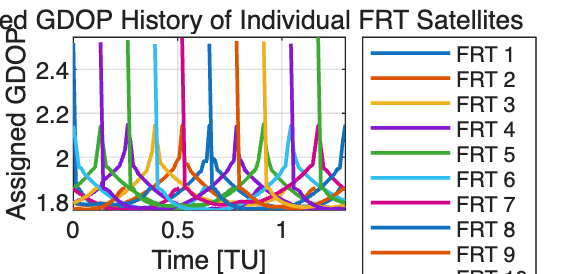

%% ========================================================================
% VI. ALL-TIME CENTRALIZED / DISTRIBUTED ASSIGNMENT
% ========================================================================

nTime = size(topK_GDOP_history,1);
N_FRT = size(topK_GDOP_history,2);

%% ------------------------------------------------------------------------
% Capacity
% -------------------------------------------------------------------------

capacity_NRHO = ones(N_NRHO,1) * 2;
capacity_L4   = ones(N_L4,1)   * 2;
capacity_L5   = ones(N_L5,1)   * 2;


%% ------------------------------------------------------------------------
% Preallocation - Centralized
% -------------------------------------------------------------------------

central_success_history   = false(nTime,1);
central_objective_history = NaN(nTime,1);
central_runtime_history   = NaN(nTime,1);

central_rank_history      = NaN(nTime,N_FRT);
central_GDOP_history      = NaN(nTime,N_FRT);

central_NRHO_history      = NaN(nTime,N_FRT);
central_L4_history        = NaN(nTime,N_FRT);
central_L5_history        = NaN(nTime,N_FRT);


%% ------------------------------------------------------------------------
% Preallocation - Distributed Sequential
% -------------------------------------------------------------------------

distributed_success_history   = false(nTime,1);
distributed_objective_history = NaN(nTime,1);
distributed_runtime_history   = NaN(nTime,1);

distributed_rank_history      = NaN(nTime,N_FRT);
distributed_GDOP_history      = NaN(nTime,N_FRT);

distributed_NRHO_history      = NaN(nTime,N_FRT);
distributed_L4_history        = NaN(nTime,N_FRT);
distributed_L5_history        = NaN(nTime,N_FRT);


%% ========================================================================
% Solve all timesteps
% ========================================================================

for time_index = 1:nTime

    % fprintf( ...
    %     '\n====================================================\n');
    % fprintf( ...
    %     'Assignment timestep %d / %d\n', ...
    %     time_index, nTime);
    % fprintf( ...
    %     '====================================================\n');


    %% ====================================================================
    % 1. Centralized
    % ====================================================================

    tic;

    central_i = solveCentralizedGDOPAssignment( ...
        time_index, ...
        topK_GDOP_history, ...
        topK_NRHO_ID_history, ...
        topK_L4_ID_history, ...
        topK_L5_ID_history, ...
        capacity_NRHO, ...

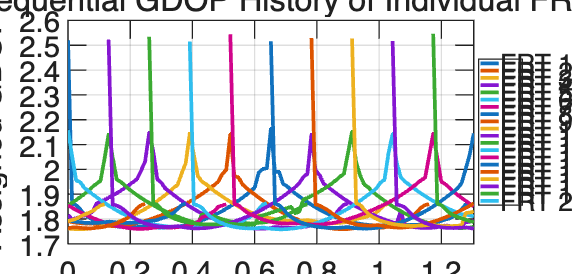

        capacity_L4, ...
        capacity_L5);

    central_runtime_history(time_index) = toc;


    %% Store success / objective

    central_success_history(time_index) = ...
        central_i.success;

    central_objective_history(time_index) = ...
        central_i.objective;


    %% Store satellite-level results

    if central_i.success

        central_rank_history(time_index,:) = ...
            central_i.rank';

        central_GDOP_history(time_index,:) = ...
            central_i.GDOP';

        central_NRHO_history(time_index,:) = ...
            central_i.NRHO_ID';

        central_L4_history(time_index,:) = ...
            central_i.L4_ID';

        central_L5_history(time_index,:) = ...
            central_i.L5_ID';

    end


    %% ====================================================================
    % 2. Distributed Sequential
    % ====================================================================

    decision_order = ...
        1:N_FRT;

    tic;

    distributed_i = solveDistributedSequential( ...
        time_index, ...
        topK_GDOP_history, ...
        topK_NRHO_ID_history, ...
        topK_L4_ID_history, ...
        topK_L5_ID_history, ...
        capacity_NRHO, ...
        capacity_L4, ...
        capacity_L5, ...
        decision_order);

    distributed_runtime_history(time_index) = toc;


    %% Store success / objective

    distributed_success_history(time_index) = ...
        distributed_i.success;

    distributed_objective_history(time_index) = ...
        distributed_i.objective;


    %% Store satellite-level results

    if distributed_i.success

        distributed_rank_history(time_index,:) = ...
            distributed_i.rank';

        distributed_GDOP_history(time_index,:) = ...
            distributed_i.GDOP';


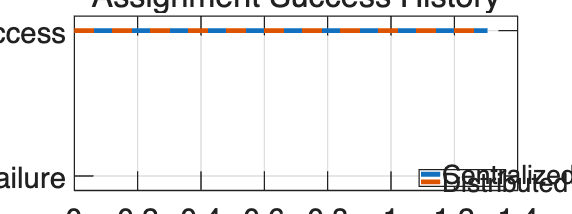

        distributed_NRHO_history(time_index,:) = ...
            distributed_i.NRHO_ID';

        distributed_L4_history(time_index,:) = ...
            distributed_i.L4_ID';

        distributed_L5_history(time_index,:) = ...
            distributed_i.L5_ID';

    end

end

%% ========================================================================
% VII. SUCCESS CHECK
% ========================================================================

all_central_success = ...
    all(central_success_history);

all_distributed_success = ...
    all(distributed_success_history);

all_methods_success = ...
    all_central_success && ...
    all_distributed_success;


fprintf('\n');
fprintf('====================================================\n');
fprintf('ALL-TIME ASSIGNMENT SUCCESS SUMMARY\n');
fprintf('====================================================\n');

fprintf( ...
    'Centralized Success   : %d / %d\n', ...
    sum(central_success_history), ...
    nTime);

fprintf( ...
    'Distributed Success   : %d / %d\n', ...
    sum(distributed_success_history), ...
    nTime);


if all_central_success
    fprintf('Centralized : ALL TIMESTEPS SUCCESS\n');
else
    fprintf('Centralized : FAILURE EXISTS\n');
end


if all_distributed_success
    fprintf('Distributed : ALL TIMESTEPS SUCCESS\n');
else
    fprintf('Distributed : FAILURE EXISTS\n');
end

%% ========================================================================
% VIII. STACK ALL ASSIGNMENT RESULTS
% ========================================================================

%% ------------------------------------------------------------------------
% Common indexing vectors
% -------------------------------------------------------------------------

TimeIndex = ...
    repmat((1:nTime)',N_FRT,1);

Time = ...
    repmat(t_vector(:),N_FRT,1);

FRTSlot = ...
    repelem((1:N_FRT)',nTime);

FRT_ID = ...
    reshape(FRT_ID_history,[],1);

FRT_PhaseAge = ...
    reshape(FRT_age_history,[],1);


%% ========================================================================
% Centralized Table
% ========================================================================

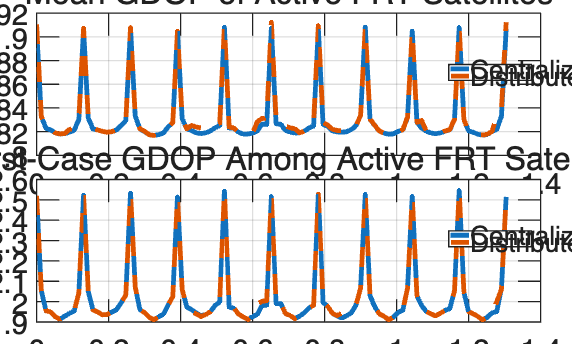


Central_Success = ...
    repmat(central_success_history,N_FRT,1);

Central_Rank = ...
    reshape(central_rank_history,[],1);

Central_GDOP = ...
    reshape(central_GDOP_history,[],1);

Central_NRHO_ID = ...
    reshape(central_NRHO_history,[],1);

Central_L4_ID = ...
    reshape(central_L4_history,[],1);

Central_L5_ID = ...
    reshape(central_L5_history,[],1);


central_assignment_table = table( ...
    TimeIndex, ...
    Time, ...
    FRTSlot, ...
    FRT_ID, ...
    FRT_PhaseAge, ...
    Central_Success, ...
    Central_Rank, ...
    Central_GDOP, ...
    Central_NRHO_ID, ...
    Central_L4_ID, ...
    Central_L5_ID);


%% ========================================================================
% Distributed Table
% ========================================================================

Distributed_Success = ...
    repmat(distributed_success_history,N_FRT,1);

Distributed_Rank = ...
    reshape(distributed_rank_history,[],1);

Distributed_GDOP = ...
    reshape(distributed_GDOP_history,[],1);

Distributed_NRHO_ID = ...
    reshape(distributed_NRHO_history,[],1);

Distributed_L4_ID = ...
    reshape(distributed_L4_history,[],1);

Distributed_L5_ID = ...
    reshape(distributed_L5_history,[],1);


distributed_assignment_table = table( ...
    TimeIndex, ...
    Time, ...
    FRTSlot, ...
    FRT_ID, ...
    FRT_PhaseAge, ...
    Distributed_Success, ...
    Distributed_Rank, ...
    Distributed_GDOP, ...
    Distributed_NRHO_ID, ...
    Distributed_L4_ID, ...
    Distributed_L5_ID);

%% ========================================================================
% IX. GDOP PERFORMANCE BY PHYSICAL FRT SATELLITE
% ========================================================================

if all_methods_success

    fprintf('\n');
    fprintf('All timesteps were successfully assigned.\n');
    fprintf('Calculating GDOP performance by physical FRT ID...\n');


    %% --------------------------------------------------------------------
    % All physical FRT IDs appearing during the simulation

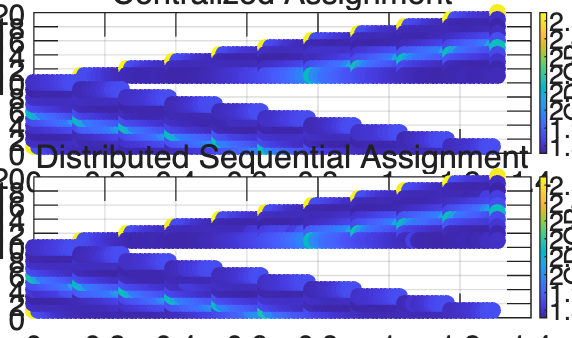

    % ---------------------------------------------------------------------

    unique_FRT_IDs = ...
        unique(FRT_ID_history(:));

    nPhysicalFRT = ...
        length(unique_FRT_IDs);


    %% --------------------------------------------------------------------
    % Preallocation
    % ---------------------------------------------------------------------

    ServiceCount = zeros(nPhysicalFRT,1);


    %% Centralized statistics

    Central_MeanGDOP   = NaN(nPhysicalFRT,1);
    Central_MedianGDOP = NaN(nPhysicalFRT,1);
    Central_MinGDOP    = NaN(nPhysicalFRT,1);
    Central_MaxGDOP    = NaN(nPhysicalFRT,1);
    Central_StdGDOP    = NaN(nPhysicalFRT,1);


    %% Distributed statistics

    Distributed_MeanGDOP   = NaN(nPhysicalFRT,1);
    Distributed_MedianGDOP = NaN(nPhysicalFRT,1);
    Distributed_MinGDOP    = NaN(nPhysicalFRT,1);
    Distributed_MaxGDOP    = NaN(nPhysicalFRT,1);
    Distributed_StdGDOP    = NaN(nPhysicalFRT,1);


    %% ====================================================================
    % Physical ID loop
    % ====================================================================

    for ii = 1:nPhysicalFRT

        current_ID = ...
            unique_FRT_IDs(ii);


        %% -------------------------------------------------------------
        % Centralized
        % -------------------------------------------------------------

        idx_central = ...
            central_assignment_table.FRT_ID == current_ID;

        gdop_central = ...
            central_assignment_table.Central_GDOP(idx_central);

        gdop_central = ...
            gdop_central(isfinite(gdop_central));


        %% -------------------------------------------------------------
        % Distributed
        % -------------------------------------------------------------

        idx_distributed = ...
            distributed_assignment_table.FRT_ID == current_ID;

        gdop_distributed = ...
            distributed_assignment_table.Distributed_GDOP( ...
                idx_distributed);

        gdop_distributed = ...
            gdop_distributed(isfinite(gdop_distributed));



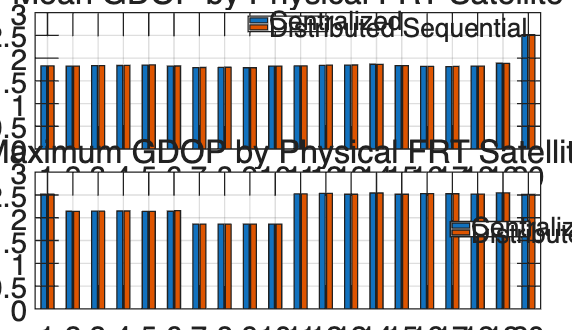

        %% -------------------------------------------------------------
        % Service count
        % -------------------------------------------------------------

        ServiceCount(ii) = ...
            length(gdop_central);


        %% -------------------------------------------------------------
        % Centralized statistics
        % -------------------------------------------------------------

        if ~isempty(gdop_central)

            Central_MeanGDOP(ii) = ...
                mean(gdop_central);

            Central_MedianGDOP(ii) = ...
                median(gdop_central);

            Central_MinGDOP(ii) = ...
                min(gdop_central);

            Central_MaxGDOP(ii) = ...
                max(gdop_central);

            Central_StdGDOP(ii) = ...
                std(gdop_central);

        end


        %% -------------------------------------------------------------
        % Distributed statistics
        % -------------------------------------------------------------

        if ~isempty(gdop_distributed)

            Distributed_MeanGDOP(ii) = ...
                mean(gdop_distributed);

            Distributed_MedianGDOP(ii) = ...
                median(gdop_distributed);

            Distributed_MinGDOP(ii) = ...
                min(gdop_distributed);

            Distributed_MaxGDOP(ii) = ...
                max(gdop_distributed);

            Distributed_StdGDOP(ii) = ...
                std(gdop_distributed);

        end

    end


    %% ====================================================================
    % Comparison
    % ====================================================================

    MeanGDOP_Difference = ...
        Distributed_MeanGDOP - ...
        Central_MeanGDOP;

    MeanGDOP_Degradation_percent = ...
        100 * ...
        MeanGDOP_Difference ./ ...
        Central_MeanGDOP;


    %% ====================================================================
    % Final performance table
    % ====================================================================

    FRT_GDOP_performance_table = table( ...
        unique_FRT_IDs, ...
        ServiceCount, ...
        Central_MeanGDOP, ...
        Central_MedianGDOP, ...
        Central_MinGDOP, ...
        Central_MaxGDOP, ...

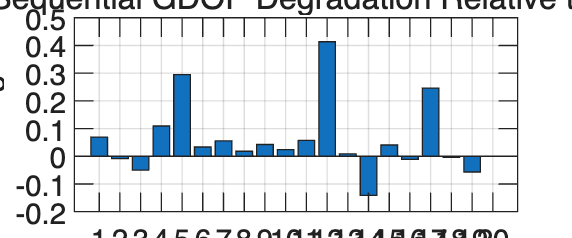

        Central_StdGDOP, ...
        Distributed_MeanGDOP, ...
        Distributed_MedianGDOP, ...
        Distributed_MinGDOP, ...
        Distributed_MaxGDOP, ...
        Distributed_StdGDOP, ...
        MeanGDOP_Difference, ...
        MeanGDOP_Degradation_percent, ...
        'VariableNames',{ ...
            'FRT_ID', ...
            'ServiceEpochCount', ...
            'Central_MeanGDOP', ...
            'Central_MedianGDOP', ...
            'Central_MinGDOP', ...
            'Central_MaxGDOP', ...
            'Central_StdGDOP', ...
            'Distributed_MeanGDOP', ...
            'Distributed_MedianGDOP', ...
            'Distributed_MinGDOP', ...
            'Distributed_MaxGDOP', ...
            'Distributed_StdGDOP', ...
            'MeanGDOP_Difference', ...
            'MeanGDOP_Degradation_Percent'});


    disp(FRT_GDOP_performance_table);


else

    warning( ...
        ['At least one assignment method failed at one or more ', ...
         'timesteps. GDOP performance table was not generated.']);


end

## Graphs

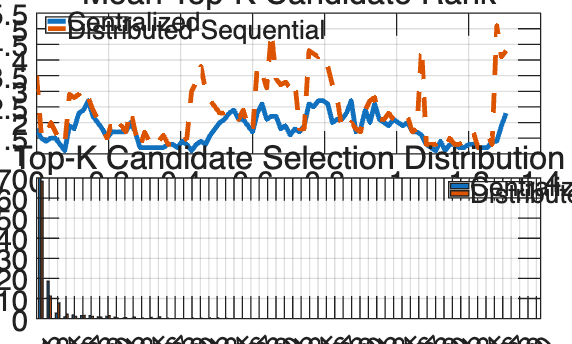

%% ========================================================================
% Individual Physical FRT Satellite GDOP History
% CENTRALIZED ASSIGNMENT
% ========================================================================

unique_FRT_IDs = ...
    unique(central_assignment_table.FRT_ID);

figure( ...
    'Name','Centralized GDOP History - Individual FRT Satellites', ...
    'Position',[100 100 1250 600]);

hold on;


for ii = 1:length(unique_FRT_IDs)

    current_ID = ...
        unique_FRT_IDs(ii);

    %% Extract current physical FRT satellite
    idx = ...
        central_assignment_table.FRT_ID == current_ID & ...
        central_assignment_table.Central_Success;

    current_time = ...
        central_assignment_table.Time(idx);

    current_GDOP = ...
        central_assignment_table.Central_GDOP(idx);


    %% Remove invalid points
    valid_idx = ...
        isfinite(current_GDOP);

    current_time = ...
        current_time(valid_idx);

    current_GDOP = ...
        current_GDOP(valid_idx);


    %% Sort by time
    [current_time,sort_idx] = ...
        sort(current_time);

    current_GDOP = ...
        current_GDOP(sort_idx);


    %% Plot
    plot( ...
        current_time, ...
        current_GDOP, ...
        'LineWidth',1.4, ...
        'DisplayName', ...
        sprintf('FRT %d',current_ID));

end


xlabel('Time [TU]');
ylabel('Assigned GDOP');

title( ...
    'Centralized GDOP History of Individual FRT Satellites');

legend( ...
    'Location','eastoutside');

xlim([t_vector(1) t_vector(end)]);

grid on;
box on;

hold off;

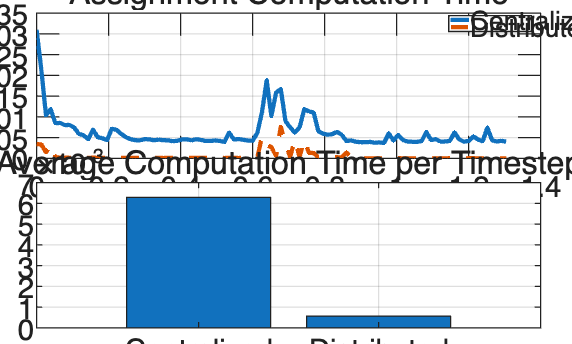

%% ========================================================================
% Individual Physical FRT Satellite GDOP History
% DISTRIBUTED SEQUENTIAL ASSIGNMENT
% ========================================================================

unique_FRT_IDs = ...
    unique(distributed_assignment_table.FRT_ID);

figure( ...
    'Name','Distributed GDOP History - Individual FRT Satellites', ...
    'Position',[100 100 1250 600]);

hold on;


for ii = 1:length(unique_FRT_IDs)

    current_ID = ...
        unique_FRT_IDs(ii);

    %% Extract current physical FRT satellite
    idx = ...
        distributed_assignment_table.FRT_ID == current_ID & ...
        distributed_assignment_table.Distributed_Success;

    current_time = ...
        distributed_assignment_table.Time(idx);

    current_GDOP = ...
        distributed_assignment_table.Distributed_GDOP(idx);


    %% Remove invalid points
    valid_idx = ...
        isfinite(current_GDOP);

    current_time = ...
        current_time(valid_idx);

    current_GDOP = ...
        current_GDOP(valid_idx);


    %% Sort by time
    [current_time,sort_idx] = ...
        sort(current_time);

    current_GDOP = ...
        current_GDOP(sort_idx);


    %% Plot
    plot( ...
        current_time, ...
        current_GDOP, ...
        'LineWidth',1.4, ...
        'DisplayName', ...
        sprintf('FRT %d',current_ID));

end


xlabel('Time [TU]');
ylabel('Assigned GDOP');

title( ...
    'Distributed Sequential GDOP History of Individual FRT Satellites');

legend( ...

    'Location','eastoutside');

xlim([t_vector(1) t_vector(end)]);

grid on;
box on;

hold off;

Another Graphs

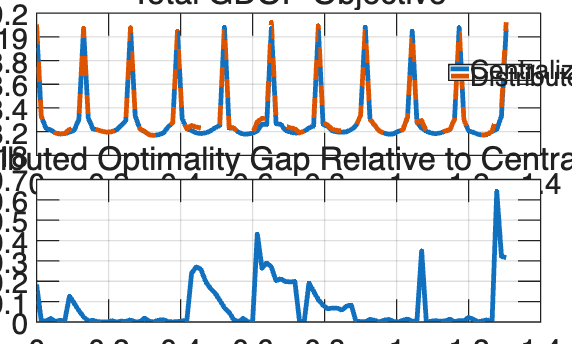

%% ========================================================================
% XIV. PLOT ALL RESULTS
% ========================================================================

%% ------------------------------------------------------------------------
% Remove Inf for plotting/statistics
% -------------------------------------------------------------------------

central_GDOP_plot = central_GDOP_history;
distributed_GDOP_plot = distributed_GDOP_history;

central_GDOP_plot(~isfinite(central_GDOP_plot)) = NaN;
distributed_GDOP_plot(~isfinite(distributed_GDOP_plot)) = NaN;


%% ------------------------------------------------------------------------
% Time-wise statistics
% -------------------------------------------------------------------------

central_mean_GDOP_time = ...
    mean(central_GDOP_plot,2,'omitnan');

central_max_GDOP_time = ...
    max(central_GDOP_plot,[],2,'omitnan');

central_min_GDOP_time = ...
    min(central_GDOP_plot,[],2,'omitnan');


distributed_mean_GDOP_time = ...
    mean(distributed_GDOP_plot,2,'omitnan');

distributed_max_GDOP_time = ...
    max(distributed_GDOP_plot,[],2,'omitnan');

distributed_min_GDOP_time = ...
    min(distributed_GDOP_plot,[],2,'omitnan');


%% ========================================================================
% FIGURE 1
% Assignment Success History
% ========================================================================

figure( ...
    'Name','Assignment Success History', ...
    'Position',[100 100 1200 450]);

hold on;

stairs( ...
    t_vector, ...
    double(central_success_history), ...
    'LineWidth',1.8);

stairs( ...
    t_vector, ...
    double(distributed_success_history), ...
    '--', ...
    'LineWidth',1.8);

xlabel('Time [TU]');
ylabel('Assignment Success');

title('Assignment Success History');

legend( ...
    'Centralized', ...
    'Distributed Sequential', ...
    'Location','best');

yticks([0 1]);
yticklabels({'Failure','Success'});

ylim([-0.1 1.1]);


grid on;
box on;

hold off;


%% ========================================================================
% FIGURE 2
% Mean / Worst-Case GDOP vs Time
% ========================================================================

figure( ...
    'Name','GDOP Performance vs Time', ...
    'Position',[100 100 1250 750]);

tiledlayout(2,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');


%% ------------------------------------------------------------------------
% Mean GDOP
% -------------------------------------------------------------------------

nexttile;

hold on;

plot( ...
    t_vector, ...
    central_mean_GDOP_time, ...
    'LineWidth',1.8);

plot( ...
    t_vector, ...
    distributed_mean_GDOP_time, ...
    '--', ...
    'LineWidth',1.8);

ylabel('Mean GDOP');

title('Mean GDOP of Active FRT Satellites');

legend( ...
    'Centralized', ...
    'Distributed Sequential', ...
    'Location','best');

grid on;
box on;

hold off;


%% ------------------------------------------------------------------------
% Worst-case GDOP
% -------------------------------------------------------------------------

nexttile;

hold on;

plot( ...
    t_vector, ...
    central_max_GDOP_time, ...
    'LineWidth',1.8);

plot( ...
    t_vector, ...
    distributed_max_GDOP_time, ...
    '--', ...
    'LineWidth',1.8);

xlabel('Time [TU]');
ylabel('Worst-Case GDOP');

title('Worst-Case GDOP Among Active FRT Satellites');

legend( ...
    'Centralized', ...
    'Distributed Sequential', ...
    'Location','best');

grid on;
box on;

hold off;


%% ========================================================================
% FIGURE 3
% Physical FRT Satellite ID - GDOP Lookup Map
% ========================================================================

if all_methods_success

    figure( ...
        'Name','Physical FRT GDOP Lookup Map', ...
        'Position',[100 100 1350 800]);

    tiledlayout(2,1, ...
        'TileSpacing','compact', ...
        'Padding','compact');


    %% --------------------------------------------------------------------
    % Centralized
    % ---------------------------------------------------------------------

    nexttile;

    valid_idx = ...
        isfinite(central_assignment_table.Central_GDOP);

    scatter( ...
        central_assignment_table.Time(valid_idx), ...
        central_assignment_table.FRT_ID(valid_idx), ...
        40, ...
        central_assignment_table.Central_GDOP(valid_idx), ...
        'filled');

    ylabel('Physical FRT Satellite ID');

    title('Centralized Assignment');

    cb = colorbar;
    cb.Label.String = 'GDOP';

    grid on;
    box on;


    %% --------------------------------------------------------------------
    % Distributed
    % ---------------------------------------------------------------------

    nexttile;

    valid_idx = ...
        isfinite(distributed_assignment_table.Distributed_GDOP);

    scatter( ...
        distributed_assignment_table.Time(valid_idx), ...
        distributed_assignment_table.FRT_ID(valid_idx), ...
        40, ...
        distributed_assignment_table.Distributed_GDOP(valid_idx), ...
        'filled');

    xlabel('Time [TU]');
    ylabel('Physical FRT Satellite ID');

    title('Distributed Sequential Assignment');

    cb = colorbar;
    cb.Label.String = 'GDOP';

    grid on;
    box on;

end


%% ========================================================================
% FIGURE 4
% GDOP Performance by Physical FRT Satellite
% ========================================================================

if all_methods_success

    FRT_ID_plot = ...
        FRT_GDOP_performance_table.FRT_ID;


    figure( ...
        'Name','GDOP by Physical FRT Satellite', ...
        'Position',[100 100 1300 750]);

    tiledlayout(2,1, ...
        'TileSpacing','compact', ...
        'Padding','compact');


    %% --------------------------------------------------------------------
    % Mean GDOP
    % ---------------------------------------------------------------------

    nexttile;

    Y_mean = [
        FRT_GDOP_performance_table.Central_MeanGDOP, ...
        FRT_GDOP_performance_table.Distributed_MeanGDOP
        ];

    bar( ...
        FRT_ID_plot, ...
        Y_mean);

    ylabel('Mean GDOP');

    title('Mean GDOP by Physical FRT Satellite');

    legend( ...
        'Centralized', ...
        'Distributed Sequential', ...
        'Location','best');

    xticks(FRT_ID_plot);

    grid on;
    box on;


    %% --------------------------------------------------------------------
    % Maximum GDOP
    % ---------------------------------------------------------------------

    nexttile;

    Y_max = [
        FRT_GDOP_performance_table.Central_MaxGDOP, ...
        FRT_GDOP_performance_table.Distributed_MaxGDOP
        ];

    bar( ...
        FRT_ID_plot, ...
        Y_max);

    xlabel('Physical FRT Satellite ID');
    ylabel('Maximum GDOP');

    title('Maximum GDOP by Physical FRT Satellite');

    legend( ...
        'Centralized', ...
        'Distributed Sequential', ...
        'Location','best');

    xticks(FRT_ID_plot);

    grid on;
    box on;

end


%% ========================================================================
% FIGURE 5
% Distributed GDOP Degradation by Physical FRT Satellite
% ========================================================================

if all_methods_success

    figure( ...
        'Name','Distributed GDOP Degradation', ...
        'Position',[100 100 1200 500]);

    bar( ...
        FRT_GDOP_performance_table.FRT_ID, ...
        FRT_GDOP_performance_table.MeanGDOP_Degradation_Percent);

    xlabel('Physical FRT Satellite ID');
    ylabel('Mean GDOP Degradation [%]');

    title( ...
        'Distributed Sequential GDOP Degradation Relative to Centralized');

    yline( ...
        0, ...
        '--');

    xticks( ...
        FRT_GDOP_performance_table.FRT_ID);

    grid on;
    box on;

end


%% ========================================================================
% FIGURE 6
% Selected Candidate Rank Performance
% ========================================================================

if all_methods_success

    %% Number of Top-K candidates
    K = size(topK_GDOP_history,3);

    %% --------------------------------------------------------------------
    % Mean rank at each timestep
    % ---------------------------------------------------------------------

    central_mean_rank_time = ...
        mean(central_rank_history,2,'omitnan');

    distributed_mean_rank_time = ...
        mean(distributed_rank_history,2,'omitnan');


    figure( ...
        'Name','Candidate Rank Performance', ...
        'Position',[100 100 1250 750]);

    tiledlayout(2,1, ...
        'TileSpacing','compact', ...
        'Padding','compact');


    %% --------------------------------------------------------------------
    % Mean selected rank
    % ---------------------------------------------------------------------

    nexttile;

    hold on;

    plot( ...
        t_vector, ...
        central_mean_rank_time, ...
        'LineWidth',1.8);

    plot( ...
        t_vector, ...
        distributed_mean_rank_time, ...
        '--', ...
        'LineWidth',1.8);

    ylabel('Mean Selected Rank');

    title('Mean Top-K Candidate Rank');

    legend( ...
        'Centralized', ...
        'Distributed Sequential', ...
        'Location','best');

    grid on;
    box on;

    hold off;


    %% --------------------------------------------------------------------
    % Rank histogram
    % ---------------------------------------------------------------------

    nexttile;

    rank_axis = 1:K;

    central_rank_count = ...
        zeros(K,1);

    distributed_rank_count = ...
        zeros(K,1);


    for k = 1:K

        central_rank_count(k) = ...
            sum(central_rank_history(:) == k);

        distributed_rank_count(k) = ...
            sum(distributed_rank_history(:) == k);

    end


    %% --------------------------------------------------------------------
    % Percentage
    % ---------------------------------------------------------------------

    central_total = ...
        sum(central_rank_count);

    distributed_total = ...
        sum(distributed_rank_count);


    central_rank_percentage = ...
        100 * central_rank_count / central_total;

    distributed_rank_percentage = ...
        100 * distributed_rank_count / distributed_total;


    %% --------------------------------------------------------------------
    % Plot
    % ---------------------------------------------------------------------

    bar( ...
        rank_axis, ...
        [ ...
        central_rank_percentage, ...
        distributed_rank_percentage ...
        ]);

    xlabel('Selected Candidate Rank');
    ylabel('Selection Ratio [%]');

    title('Top-K Candidate Selection Distribution');

    legend( ...
        'Centralized', ...
        'Distributed Sequential', ...
        'Location','best');

    xticks(rank_axis);

    xlim([0.5 K+0.5]);

    grid on;
    box on;

end


%% ========================================================================
% FIGURE 7
% Runtime Comparison
% ========================================================================

figure( ...
    'Name','Computation Time Comparison', ...
    'Position',[100 100 1250 750]);

tiledlayout(2,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');


%% ------------------------------------------------------------------------
% Runtime over time
% -------------------------------------------------------------------------

nexttile;

hold on;

plot( ...
    t_vector, ...
    central_runtime_history, ...
    'LineWidth',1.6);

plot( ...
    t_vector, ...
    distributed_runtime_history, ...
    '--', ...
    'LineWidth',1.6);

ylabel('Runtime [sec]');

title('Assignment Computation Time');

legend( ...
    'Centralized', ...
    'Distributed Sequential', ...
    'Location','best');

grid on;
box on;

hold off;


%% ------------------------------------------------------------------------
% Mean runtime
% -------------------------------------------------------------------------

nexttile;

mean_runtime = [
    mean(central_runtime_history,'omitnan')
    mean(distributed_runtime_history,'omitnan')
    ];

bar( ...
    categorical({'Centralized','Distributed'}), ...
    mean_runtime);

ylabel('Mean Runtime [sec]');

title('Average Computation Time per Timestep');

grid on;
box on;


%% ========================================================================
% FIGURE 8
% Objective and Optimality Gap
% ========================================================================

if all_methods_success

    objective_gap_percent = ...
        100 * ...
        (distributed_objective_history - ...
         central_objective_history) ./ ...
        central_objective_history;


    figure( ...
        'Name','Objective Performance Comparison', ...
        'Position',[100 100 1250 750]);

    tiledlayout(2,1, ...
        'TileSpacing','compact', ...
        'Padding','compact');


    %% --------------------------------------------------------------------
    % Objective
    % ---------------------------------------------------------------------

    nexttile;

    hold on;

    plot( ...
        t_vector, ...
        central_objective_history, ...
        'LineWidth',1.8);

    plot( ...
        t_vector, ...
        distributed_objective_history, ...
        '--', ...
        'LineWidth',1.8);

    ylabel('\Sigma GDOP');

    title('Total GDOP Objective');

    legend( ...
        'Centralized', ...
        'Distributed Sequential', ...
        'Location','best');

    grid on;
    box on;

    hold off;


    %% --------------------------------------------------------------------
    % Optimality gap
    % ---------------------------------------------------------------------

    nexttile;

    plot( ...
        t_vector, ...
        objective_gap_percent, ...
        'LineWidth',1.8);

    yline( ...
        0, ...
        '--');

    xlabel('Time [TU]');
    ylabel('Optimality Gap [%]');

    title( ...
        'Distributed Optimality Gap Relative to Centralized');

    grid on;
    box on;

end